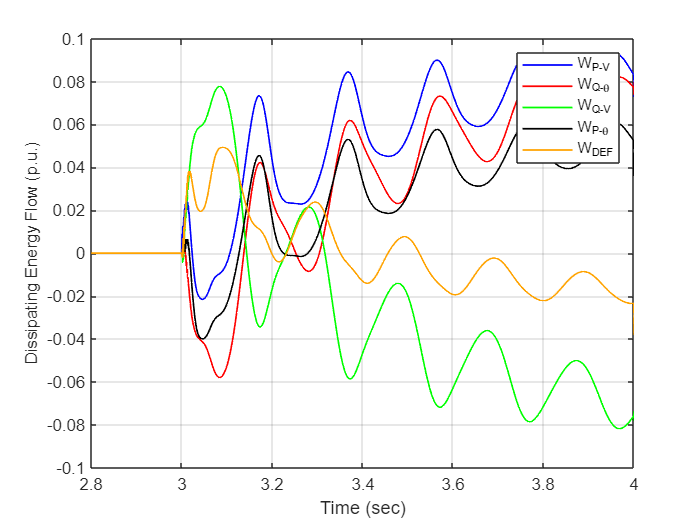

clear
clc

load def_1.mat
figure
plot(tout,simout_def1(:,1),'b','LineWidth',1);hold on;
plot(tout,simout_def1(:,2),'r','LineWidth',1)
plot(tout,simout_def1(:,3),'g','LineWidth',1)
plot(tout,simout_def1(:,4),'k','LineWidth',1)
plot(tout,simout_def1(:,5),'color','#FFA300','LineWidth',1);grid on;
legend('W_{P-V}','W_{Q-\theta}','W_{Q-V}','W_{P-\theta}','W_{DEF}');
xlim([2.8 4]);
ylabel('Dissipating Energy Flow (p.u.)','FontSize',10);
xlabel('Time (sec)');

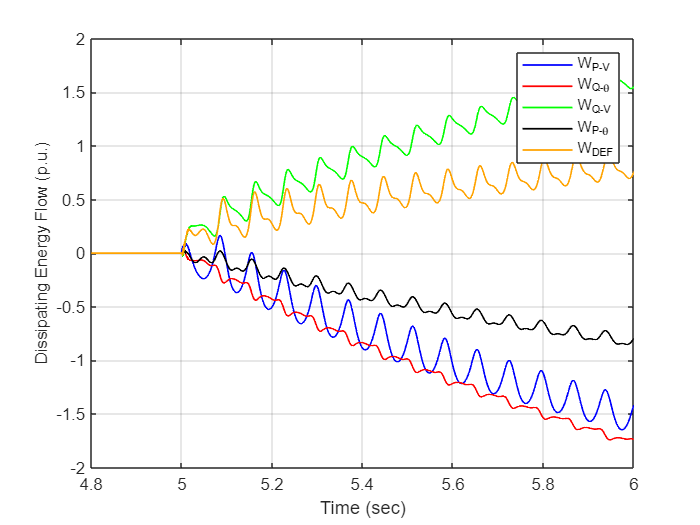


load def_2.mat
figure
plot(tout,simout_def2(:,1),'b','LineWidth',1);hold on;
plot(tout,simout_def2(:,2),'r','LineWidth',1)
plot(tout,simout_def2(:,3),'g','LineWidth',1)
plot(tout,simout_def2(:,4),'k','LineWidth',1)
plot(tout,simout_def2(:,5),'color','#FFA300','LineWidth',1);grid on;
legend('W_{P-V}','W_{Q-\theta}','W_{Q-V}','W_{P-\theta}','W_{DEF}');
xlim([4.8 6]);
ylabel('Dissipating Energy Flow (p.u.)','FontSize',10);
xlabel('Time (sec)');

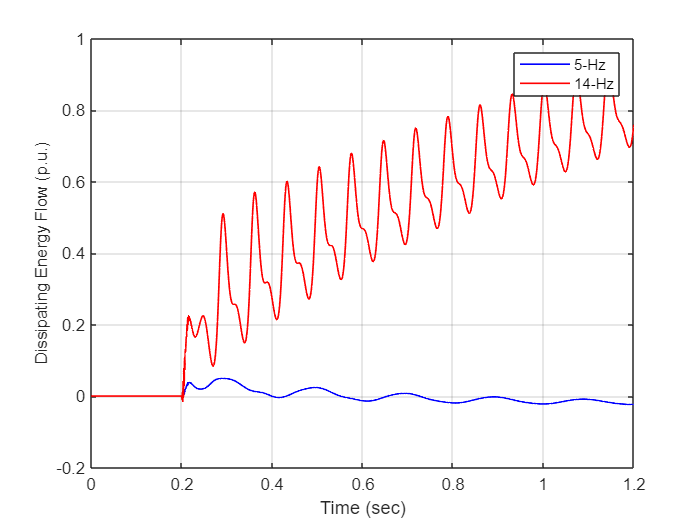


close all

tt = 0:Ts:1.2;
range1 = round(2.8/25e-6):4/25e-6;
range2 = round(4.8/25e-6):6/25e-6;
figure
plot(tt, simout_def1(range1,5),'b','LineWidth',1);hold on;
plot(tt, simout_def2(range2,5),'r','LineWidth',1);grid on;
ylabel('Dissipating Energy Flow (p.u.)','FontSize',10);
legend('5-Hz','14-Hz')
xlabel('Time (sec)');